images\seashell_five.jpg


Method used: meanfilter


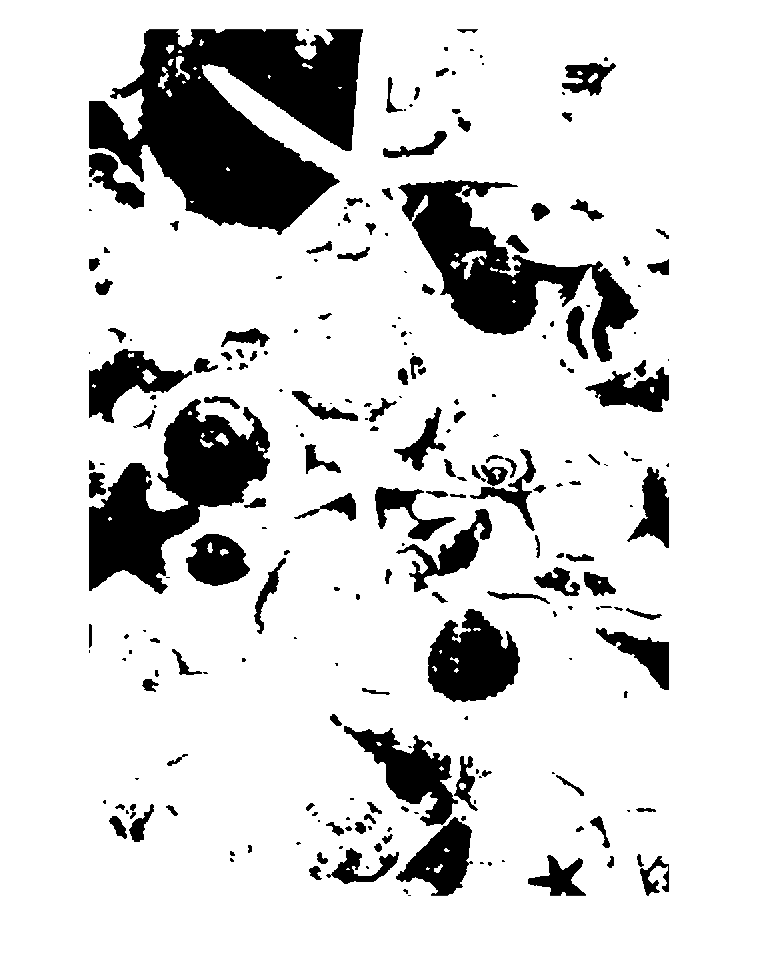

images\shellfish_four.jpg


Method used: meanfilter


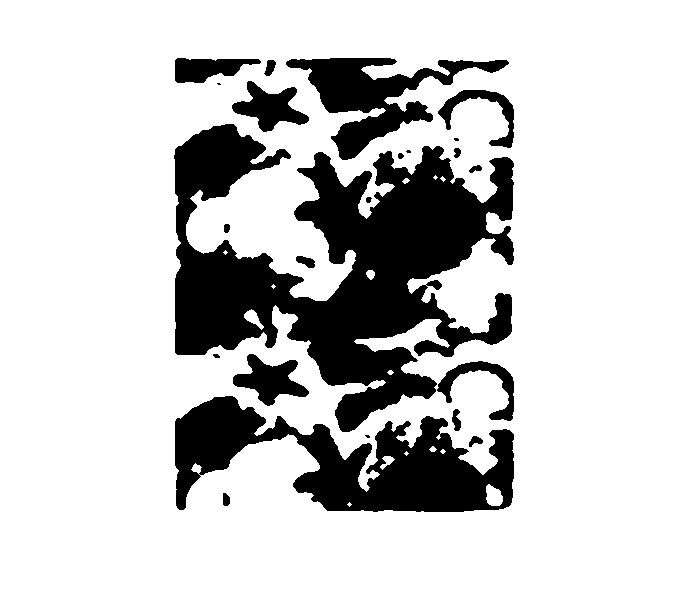

images\starfish.jpg


Method used: meanfilter


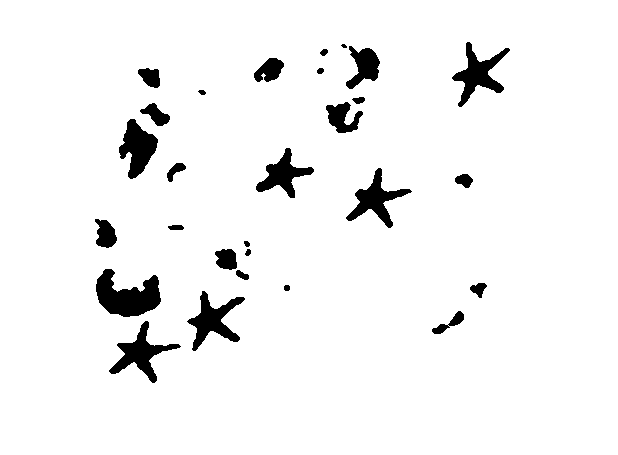

images\starfish_17.jpg


Method used: meanfilter


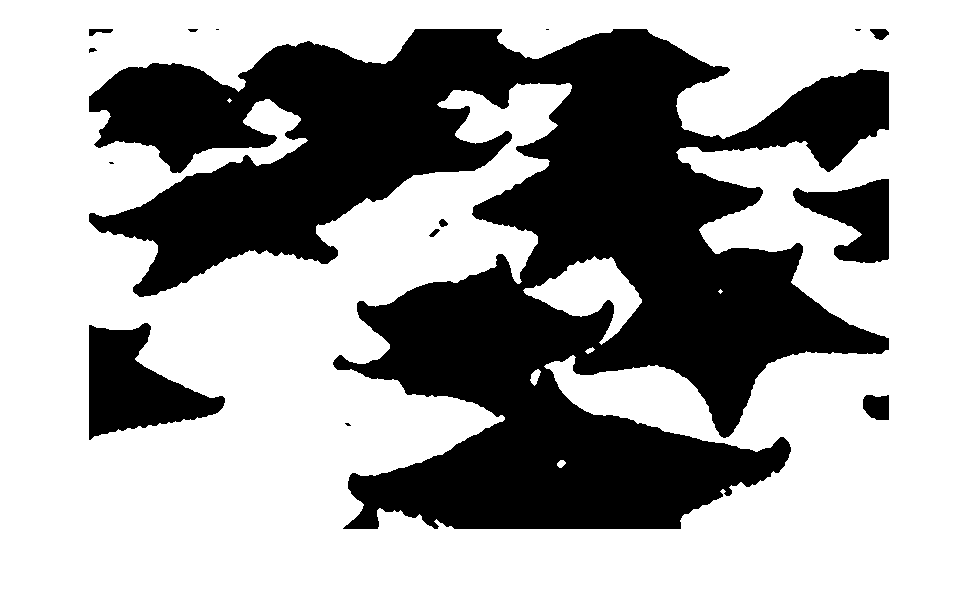

images\starfish_5.jpg


Method used: meanfilter


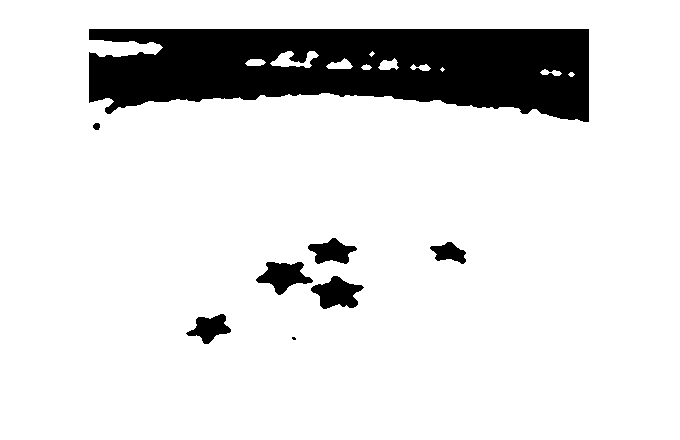

images\starfish_map0.jpg


Method used: meanfilter


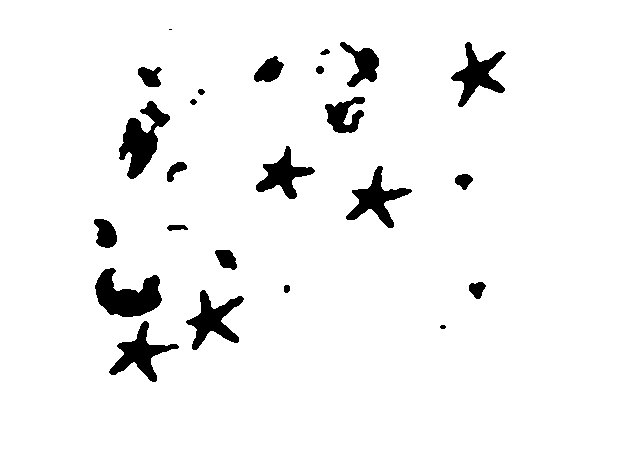

images\starfish_map1.jpg


Method used: meanfilter


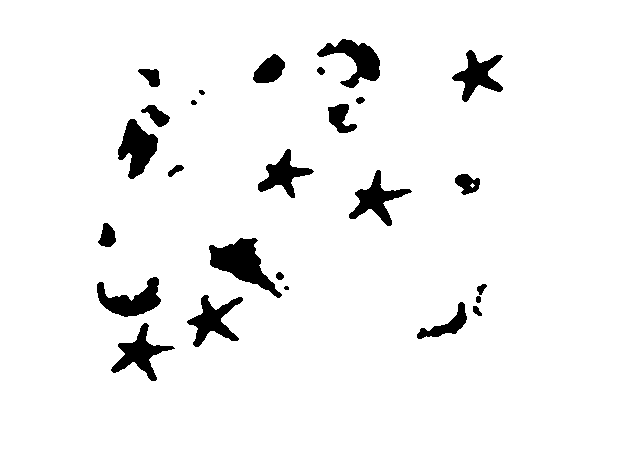

images\starfish_map2.jpg


Method used: meanfilter


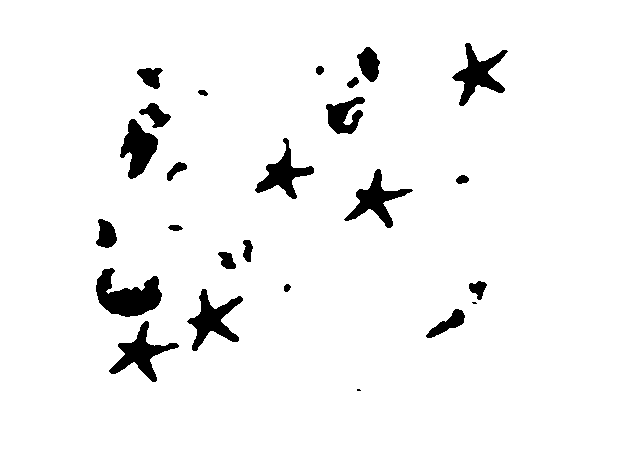

images\starfish_map3.jpg


Method used: meanfilter


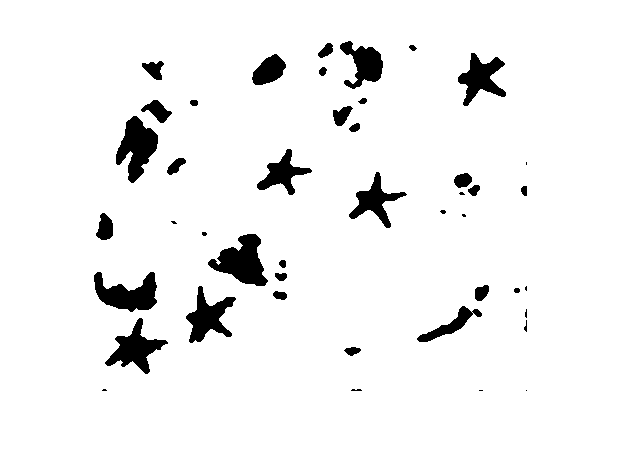

images\starfish_noise1.jpg


Method used: meanfilter


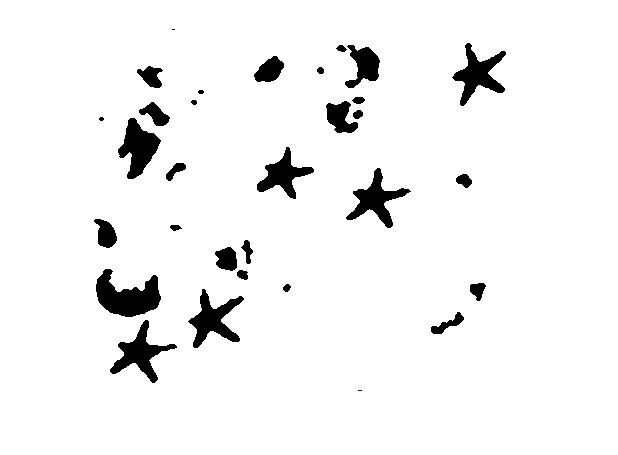

images\starfish_noise10.jpg


Method used: meanfilter


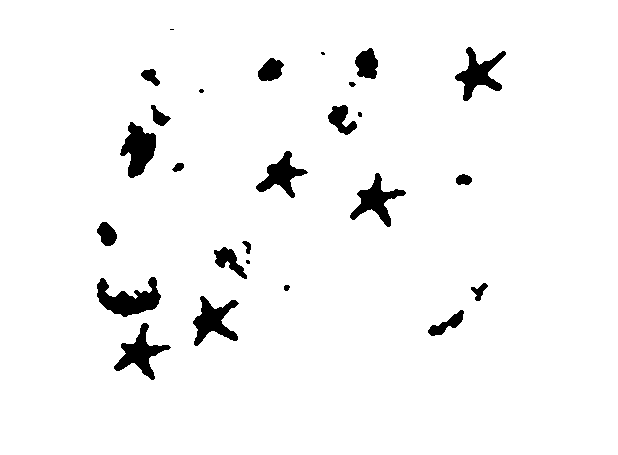

images\starfish_noise2.jpg


Method used: meanfilter


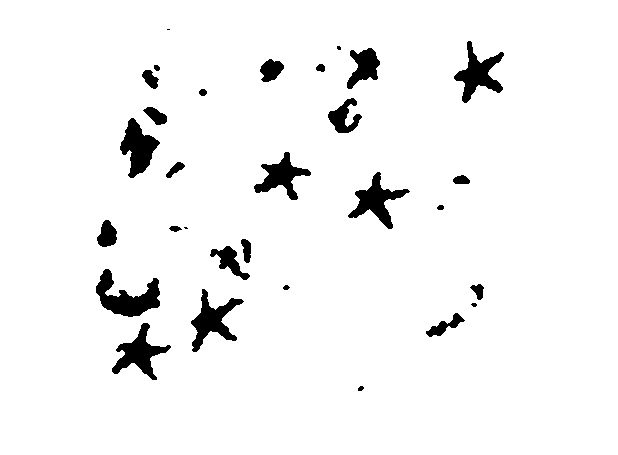

images\starfish_noise3.jpg


Method used: meanfilter


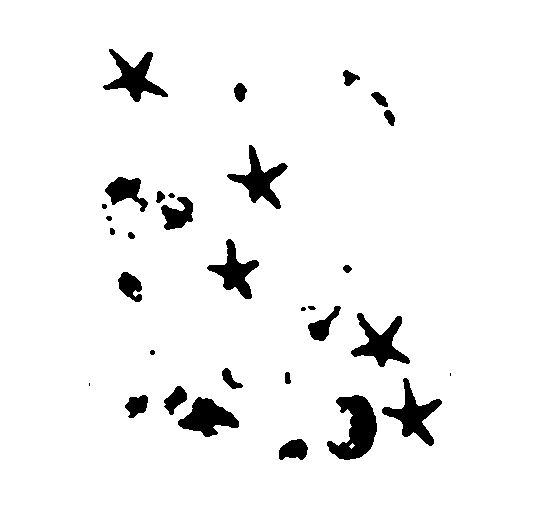

images\starfish_noise4.jpg


Method used: meanfilter


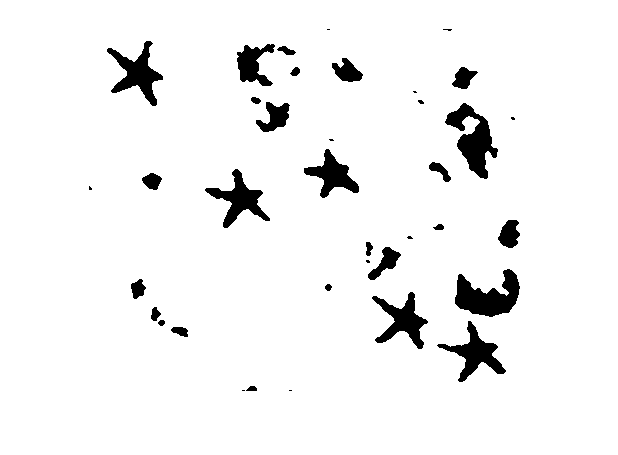

images\starfish_noise5.jpg


Method used: meanfilter


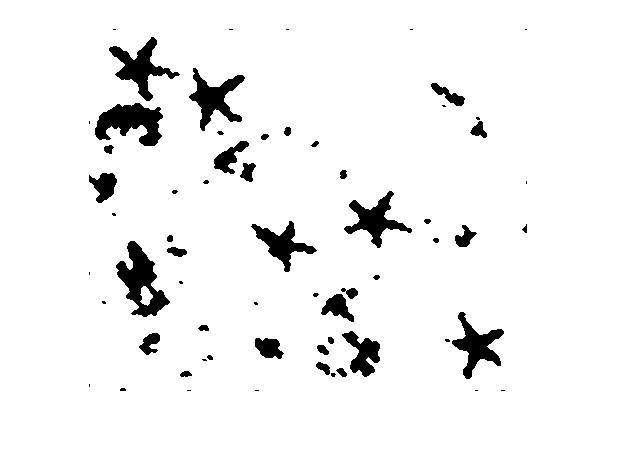

images\starfish_noise6.jpg


Method used: meanfilter


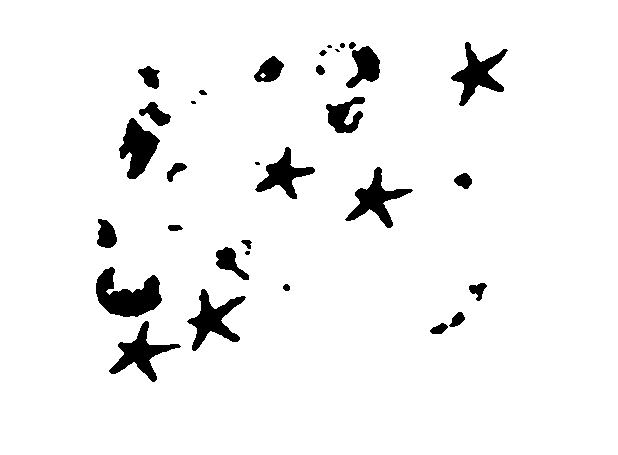

images\starfish_noise7.jpg


Method used: meanfilter


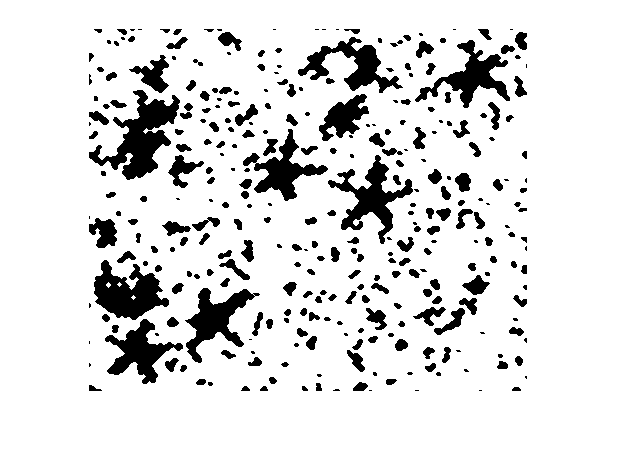

images\starfish_noise8.jpg


Method used: meanfilter


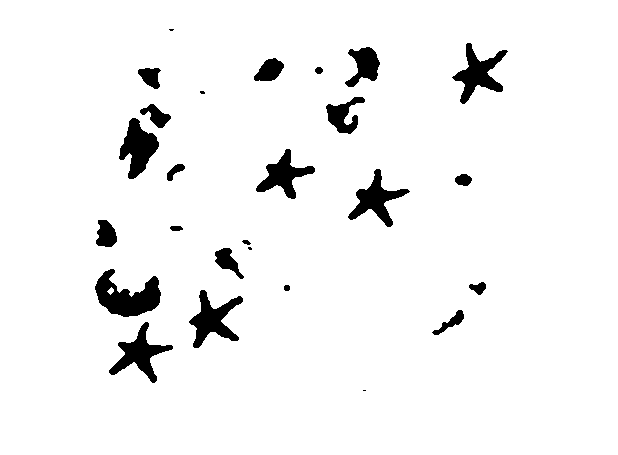

images\starfish_noise9.jpg


Method used: meanfilter


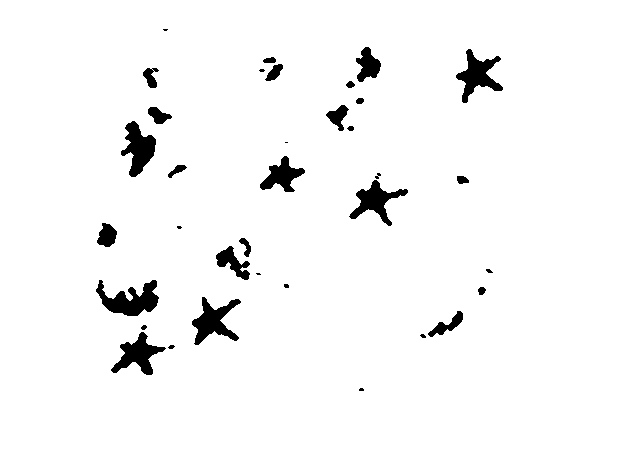

images\starfish_overlaid.jpg


Method used: meanfilter


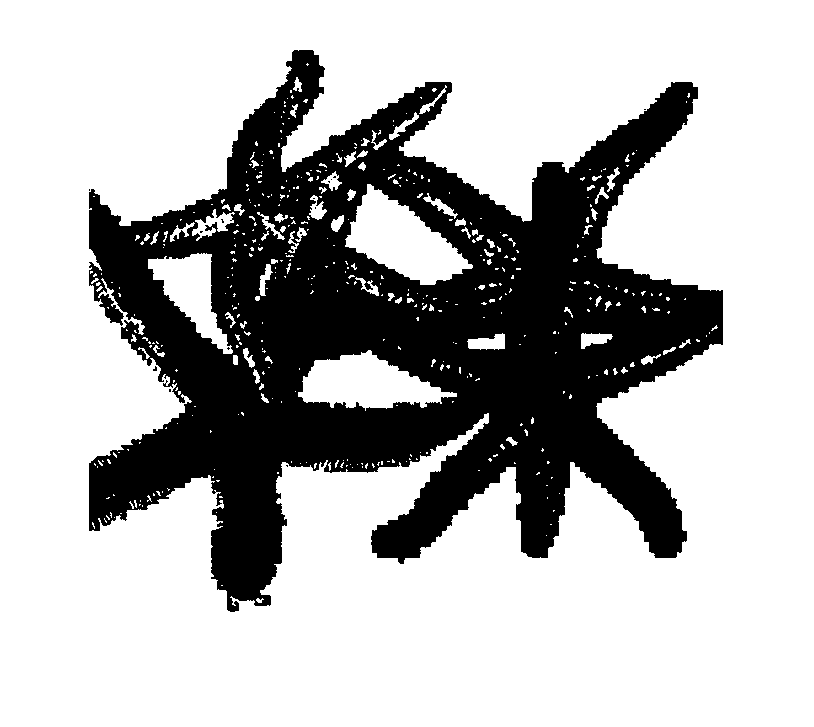

Process()

function Process()
    files = GetFilesInSubDir("images");
    
    for i = 1:numel(files)
        figure
        filepath = files(i);
        disp(filepath)
        
        im = imread(filepath);
        imshow(im);
        
        im = DenoiseIsolated(im, 'meanfilter');
        im = imfilter(im, ones(3)/9, 'same');
        imshow(im);
        
        im = rgb2hsv(im);
        [c1,c2,c3] = imsplit(im);
        im = c2;
        imshow(im);
        
        level = graythresh(im);
        im = imbinarize(im, level);
        im = ~im;
        imshow(~im);
    
        se = strel('disk', 2);
        im = imopen(im, se); % Helps with the noiser images.
        
        se = strel('line', 3, 0);
        im = imclose(im, se);
        se = strel('line', 3, 45);
        im = imclose(im, se);
        se = strel('line', 3, 90);
        im = imclose(im, se);
        se = strel('line', 3, 135);
        im = imclose(im, se);
        se = strel('line', 3, 180);
        im = imclose(im, se);
        imshow(im);
    end
end


function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end
% % % %


function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %


function noisePercent = GetRelPercentageNoise(im, noiseMask)
noisyPixels = sum(noiseMask(:));
nPx = numel(im);
noisePercent = (100/nPx) * noisyPixels;
end
% % % %


function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;

    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
%     if (noiseValue > 30)
%         disp("Switching mode");
%         method = "meanfilter";
%         repeat = true;
%     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %